# **Introducing the simulink model for 1. Ton vehicle.**

**requirements of a BCS**

**1)refrigirant pump**

**2)radiators - 2 or 3 numbers **

**3)expansion device **

**4)heat exhancging device 5)coolant lines **

**6)coolant pump**

**7)coolant(50-50 ethanol/glycol)**

**8)de-aeration tank **

**9)coolant reservoir tank **

## ***We have calculated all the energy requirements with respect to ******WLTP class****** 1 drive cycle.*** 

Energy requirement and battery pack sizing was 23.790Kwh requirement. 

Assuming that the vehicle operates at 96V system in relative to current to minize the current value. 

The Value of current is: 

**V * I  =  23,790Watts**

**V = 96Volts**

**I = 250Amp**

**The heat generated by the cell is I^2*R where R is the internal resistance of the cell and equal to 0.00037 as per the manufacturer **

whos 

  Name                     Size            Bytes  Class     Attributes

  Current               1023x1              8184  double              
  Speed                 1023x1              9071  table               
  Totalelapsedtime      1023x1              8184  double              



As we can see the amp and cvalues stored are in table format

to convert them back into double format we use the **table2array** function

now we can perform if condition and run the loop to estimate values or simply divide the amp /100 to get C ratings in this case

%current=table2array(current)
speed=table2array(Speed)

speed =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


%% importing the variables in the workspace in double format instead of typical table format 

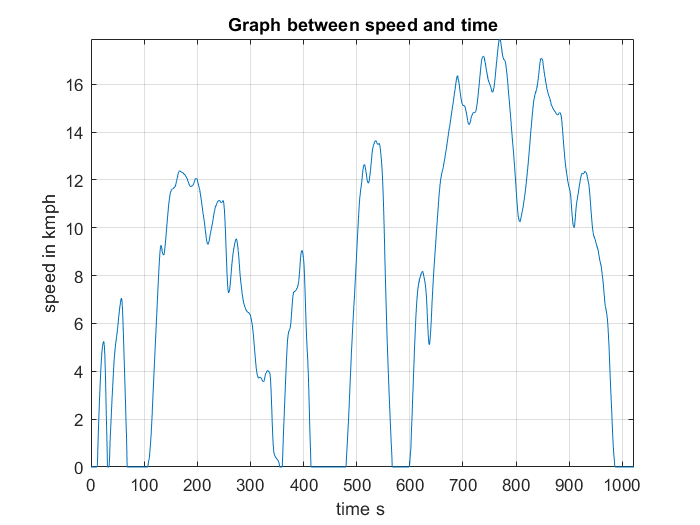

%%plotting the main graph 
plot(Totalelapsedtime,speed)
xlabel("time s ")
ylabel("speed in kmph")
title("Graph between speed and time")
axis tight 
grid on

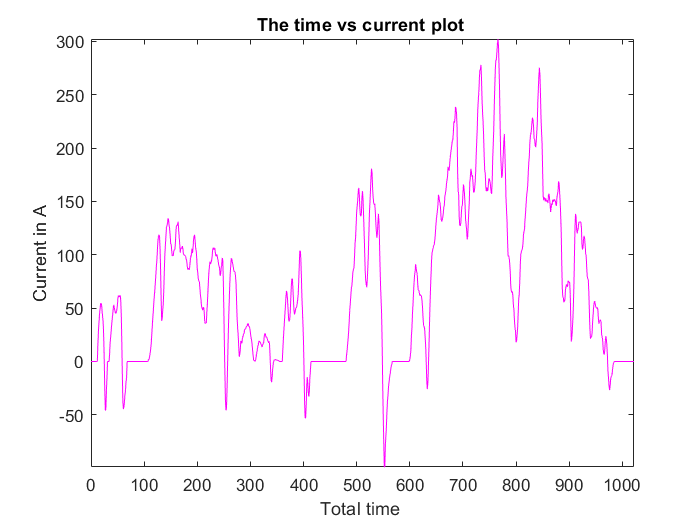

plot(Totalelapsedtime,Current,"m")
axis tight 
xlabel("Total time ")
ylabel("Current in A")
title("The time vs current plot ")

Now we can import the heat generated in Watts by the EV battery with reference to the WLTP class 1 cycle

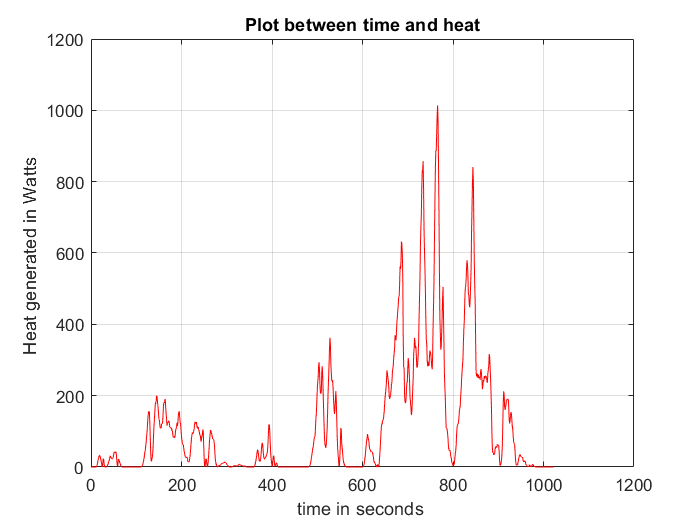

plot(Totalelapsedtime,Heattotalpack,"r-")
xlabel("time in seconds ")
ylabel("Heat generated in Watts ")
title("Plot between time and heat")
grid on

We can observe that the maximum heat generated is at 769th index equal to value of roughly 1KW. 

This is the maximum amount of energy that is lost in heat. 

avgheat=mean(Heattotalpack)

avgheat = 116.1467

disp("The average Heat generated by the battery discharge in WLTP cycle is:" );disp(avgheat);

The average Heat generated by the battery discharge in WLTP cycle is:
  116.1467



%%this shows the heat generated for this cycle 

Next task is to extract the temperature range by finding out the minimum temperature and the maximum temperature

To find the temperate range using Heat energy:

**Q=M*Cp*delT** 

where delT is the temperature range. 